**Kishan Ramachandran**

**September 2018**

**CHE 363 Hw #2 Problem #2**

2 c)

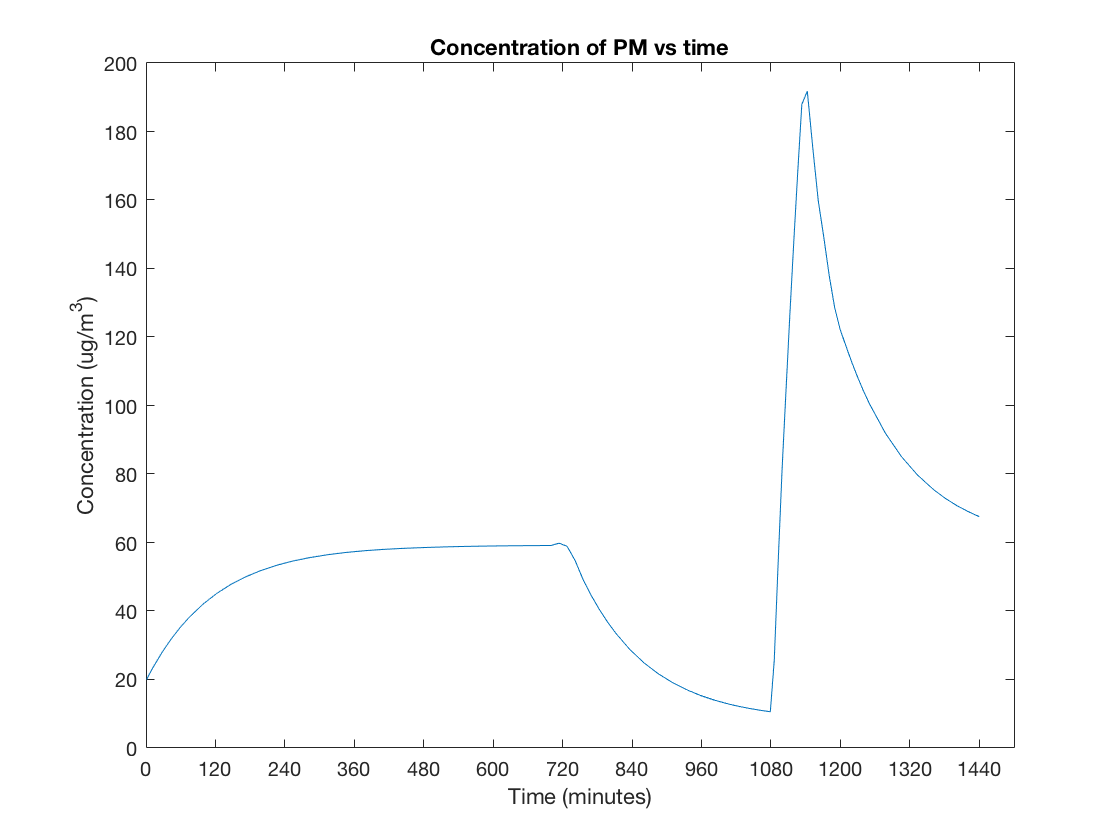

% Constant values from problem statement:
% Volume (m^3)
V = 708;
% Area (m^2)
A = 232;
% Depletion Velocity (m/min)
vd = 3.3e-4;

% Time interval (0-24 hrs in mins):
tf = 24*60;
tarr = (1:tf);
tspan = [1 tf];

% Initial conditions and disturbance variables:
% Design Air Exchange Rate (1/min)
l = 8.333e-3;
% Concentration of PM in inlet (ug/m^3)
Copm = zeros(tf,1);
Copm(1:12*60-1) = 60;
Copm(12*60:20*60-1) = 8;
Copm(20*60:24*60) = 60;
% Rate of Emission (ug/min)
Epm = zeros(tf,1);
Epm(1:7*60-1) = 0;
Epm(7*60:7.5*60-1) = 1;
Epm(7.5*60:18*60-1) = 0;
Epm(18*60:19*60-1) = 3000;
Epm(19*60:24*60) = 0;

% Concentration of PM in room (ug/m^3)
Cpm = 20;

x0 = Cpm;

% Solve ODE
[t,Cpm] = ode45(@(t,Cpm) myode(t,Cpm,tarr,Copm,Epm,l,V,vd,A),tspan,x0);

% Plots
figure(1)
plot(t,Cpm)
title("Concentration of PM vs time");
xlabel("Time (minutes)");
ylabel("Concentration (ug/m^3)");
xticks(0:120:24*60);

2 d) For the base case, we can see that from the above plot, we far exceed the recommended concentration of 40 ug/m^3

2 e) Next, a proportional controller will be implemented to help with the PM concentration in the room. The PM setpoint value will be set at 35 ug/m^3, which is just below the recommended upper bound. This is done so that if a disturbance causes an increase in the PM concentration, there will be some leeway in concentration for the controller to try to recover the CV back to the setpoint. If the setpoint was set at 40, then any disturbance could cause the CV to exceed the setpoint.

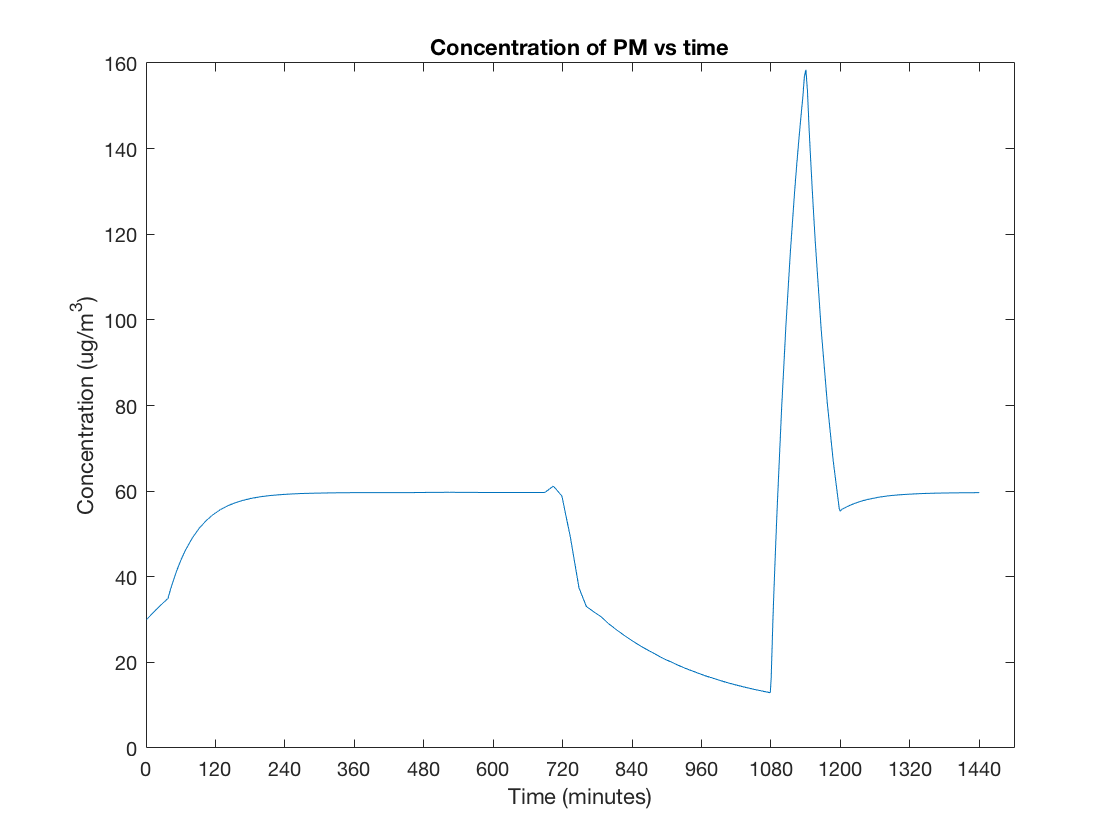

% Constant values from problem statement:
% Volume (m^3)
V = 708;
% Area (m^2)
A = 232;
% Depletion Velocity (m/min)
vd = 3.3e-4;

% Time interval (0-24 hrs in mins):
tf = 24*60;
tarr = (1:tf);
tspan = [1 tf];

% Initial conditions and disturbance variables:
% Concentration of PM in inlet (ug/m^3)
Copm = zeros(tf,1);
Copm(1:12*60-1) = 60;
Copm(12*60:20*60-1) = 8;
Copm(20*60:24*60) = 60;
% Rate of Emission (ug/min)
Epm = zeros(tf,1);
Epm(1:7*60-1) = 0;
Epm(7*60:7.5*60-1) = 1;
Epm(7.5*60:18*60-1) = 0;
Epm(18*60:19*60-1) = 3000;
Epm(19*60:24*60) = 0;

% Create proportional controller to change exchange rate to modify setpoint
% Concentration of PM in room setpoint (ug/m^3)
Cpmsp = 35;
global lold;
lold  = 8.333e-3;

% Concentration of PM in room (ug/m^3)
Cpm = 30;

x0 = Cpm;

% Solve ODE
[t,Cpm] = ode45(@(t,Cpm) propode(t,Cpm,tarr,Copm,Epm,Cpmsp,V,vd,A,lold),tspan,x0);

% Plots
figure(1)
plot(t,Cpm)
title("Concentration of PM vs time with Proportional Controller");
xlabel("Time (minutes)");
ylabel("Concentration (ug/m^3)");
xticks(0:120:24*60);

function dCpm_dt = myode(t,Cpm,tarr,Copmi,Epmi,l,V,vd,A)
Copm = interp1(tarr,Copmi,t); % Interp values of Copm and Epm at t values
Epm = interp1(tarr,Epmi,t);
dCpm_dt = (l.*(Copm-Cpm)) + ((1/V).*Epm) - ((1/V).*vd.*A.*Cpm);
end

function dCpm_dt = propode(t,Cpm,tarr,Copmi,Epmi,Cpmsp,V,vd,A,lold)
Copm = interp1(tarr,Copmi,t); % Interp values of Copm and Epm at t values
Epm = interp1(tarr,Epmi,t);
% Control k value
k = -5;
% Design Air Exchange Rate (1/min)
l = lold + k*(Cpmsp-Cpm);
% Make sure l is between 0 and 0.02
if (l < 5e-3)
    l = 5e-3;
end
if (l > 0.02)
    l = 0.02; 
end
lold = l;
dCpm_dt = (l.*(Copm-Cpm)) + ((1/V).*Epm) - ((1/V).*vd.*A.*Cpm);
end

The value of k that was chosen was negative 5. The value of 5 was used after testing various k values between 0.01 and 100 and observing the performance of the control system. At very high values, the system would overshoot the setpoint and not perform very well. At very low values, the system would not show any change from the baseline graph in part d. A negative value was used for k because logically, if the inside PM concentration was large, we would want to pump in fresh air to clear out the stagnant and contaminated air on the inside. Since the proportional control system uses a Cpm,sp - Cpm difference, a negative k value makes it so that the flow controller is opened futher when the CV exceeds the SP. When using a proportional controller, the occupants of the room are less exposed to PM over time, which can be seen upon examination of the two graphs.

f) To control the levels of all contaminants in the air, first I would write mass balances for the other two contaminants. Then, I would know the relationships between the input, output, generation, and consumption of each term. Next, I would design a controller that accounted for the set point values of these contaminants too. I would do this by calculating the differences from the setpoint to the current CV, and then looking at a K value that worked well in controlling the concentration of all three contaminants. The difficult part of this exercise would be adjusting the lambda value in a way which is beneficial to all three set point values. One way that this could be done is creating a weighted average based on the distance of a CV from the SP, and then using that distance to influence the lambda value in its favor. This would help out in cases where something like the ozone levels are extremely high in the room, which calls for a higher lambda, but the outside PM values are high. In this case, the controller would have to figure out how to manipulate the lambda value such that both levels are at their minimum.